## **Question 1**

- Consider the the Lorenz-96 model (4) with the setting used in Project 1. The data assimilation problem is posed over the interval [0, T], starting with initial background states from N (x b 0 , B0). Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from Project 1.

**The code below is taken from my Project 1 implementation.**

**1.1)**

- Implement the Lorenz-96 model (1) and solve it using a Matlab ode solver (ode45 or one integrator selected from MATLODE).

- Start with an initial condition where the states are drawn from a random distribution (e.g., x0 ∼N (0, 16)), then integrate for 5 time units. Save the result. This is our x[-1]true.

- Propagate for ∆t time units, and save. This is our reference state x[0]true.

- (You can use ∆t = 0.1.)

clear;
close all;
clc;

% Setting seed for reproducibility
rng(381996)

% Importing Lorenz96 model
m = otp.lorenz63.presets.Canonical;

% Model configurations
n_states = 3;
n_obs = 10 % Number of observations

n_obs = 10

n_obs_states = 2;
x0 = normrnd(0,sqrt(16),[n_states,1]); % Inital condition of y0 drawn from N(0,16)
dt = 0.1; % time step unit

% Solving for for 5 time units (0.5) using inital conditions above
[~, x] = ode45(m.RHS.F, [0 dt*5], x0); % This is x[-1]true/reference state.
x_true_n1 = x(end,:).'; % Extracting states at final timestep

% Propogating for dt
[~, x] = ode45(m.RHS.F, [dt*5, dt*6], x_true_n1); % This is x[-1]true/reference state
x_true = x(end,:).'; % Extracting states at final timestep

**1.2)**

- Compute Nens normal random perturbations εbi ∼ N (0, σ2 INstate ) with σ = 0.2.

- Add to x[-1]true, and integrate the system starting from the perturbed initial conditions for ∆t time units.

- Save the resulting Nens states x. The members of this ensemble represent our set of background states Xb[0] .

n_ens = 1000;
sigma = 0.2;

% create ensemble members from perturbations of x_true
eps = normrnd(0,sigma,[n_states,n_ens]); % Perturbations (note normrnd(mu,sigma))
x_perturbed_n1 = x_true_n1 + eps;  % Adding to x_true[-1]

% init storage for ensemble (background state)
X_b_ens = zeros(n_states, n_ens);

% intergate system for one time unit for each ensemble member, store result
for i = 1:n_ens
    [~, x_ens] = ode45(m.RHS.F, [dt*5, dt*6], x_perturbed_n1(:, i));
    X_b_ens(:, i) = x_ens(end, :);
end

**1.3)**

- Using a large number of ensemble members compute the ensemble covariance Pb0.

- Check its condition number. If it is large build a modified background covariance that leads to a reasonably small condition number of the resulting covariance.

- This is our B0.

% A problem is called well-conditioned, if its condition number is small,
% i.e., in the order of 10, 100 or 1000
% and ill-conditioned if it is large: in the order of 10^6 - 10^10, and larger.
% https://cms.uni-konstanz.de/fileadmin/archive/informatik-saupe/fileadmin/informatik/ag-saupe/Webpages/lehre/na_08/Lab1/5_CondStab/html/CondStab.html

% Inbuilt covariance method
B0 = cov(X_b_ens.');
% Manual covariance check
X_ens_mean = mean(X_b_ens, 2);
X_delta = X_b_ens - X_ens_mean;
B0_manual = (1/(n_ens-1)).*(X_delta*X_delta.');

cond(B0), cond(B0_manual)

ans = 25.2193

ans = 25.2193

% Not needed as condition number is small
alpha = 0.001;
B0_downscale = (1-alpha)*B0 + alpha*eye(n_states);
cond(B0_downscale)

ans = 18.2216

% No need as already well conditioned
%B0 = B0_downscale

**1.4) **

- Obtain x0b by selecting one state with the smallest deviation from xtrue

[M,I] = min(sum(abs(X_b_ens - x_true(end,:).')));
x0b = X_b_ens(:, I)

x0b =     7.3131
    9.2230
   26.7141



% Hack work around as x0b was very far from the truth and all analysis
% probabilties were zero.
x0b = x_true

x0b =     7.0093
    8.5893
   26.8281


**1.5)**

- Run the reference trajectory starting from x_true[0] over the interval [0, T].

- Save the solution every ∆t time units.

- At each ti = i ∆t generate N_ens synthetic observations by adding to the reference solution H*xi normal random noise drawn from N (0, R), R = r^2 I N_obs, with r = 0.025.

T = 50;
time_steps = 0:dt:T;
x_start = x_true; % Storing inital x_true[0]

X_ref = zeros(n_states, length(time_steps));
X_ref(:, 1) = x_start;

% Run forward model and save results at each timestep
for t_id = 1:(length(time_steps)-1)
    [~, x] = ode45(m.RHS.F, [time_steps(t_id) time_steps(t_id)+dt], x_start);
    X_ref(:, t_id+1) = x(end,:);
    x_start = x(end,:).'; % For next iterations, use starting conditions based on prior state

end


% Apply observation operator and add random noise to reference trajectory

% Generating observation operator (observing every odd state)
A = eye(n_obs);
M = 1;
k = 1;
N = size(A);
H = reshape([reshape(A,M,[]);zeros(k,N(1)/M*N(2))],[],N(2)).';

% Redone such to only observe the first two states (For L63)
H = [1, 0, 0; 0, 1, 0]

H =      1     0     0
     0     1     0



% Applying observation vector to reference trajectory
% H * Reference -> Observations, Clone Observatations + noise -> ensemble 
X_obvs = H * X_ref;
X_obvs_ens = repmat(X_obvs, 1,1, n_obs);

% Generating and applying observation noise (for each ensemble member)
obvs_sigma = 0.025;
R = obvs_sigma.^2 * eye(n_obs_states);
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));  % (note normrnd(mu,sigma))
X_obvs_ens = X_obvs_ens + obvs_noise;

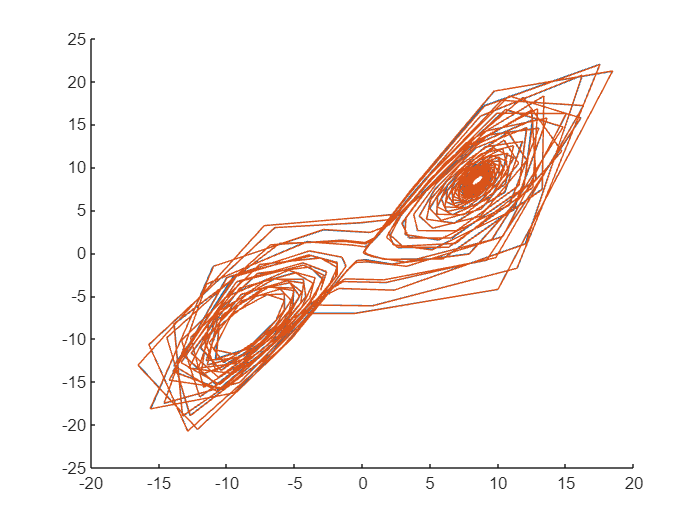

% Plotting sample reference and perturbed states (for 2 random ensemble members)
clf
hold on
plot(X_ref(1, :), X_ref(2, :));
plot(X_obvs_ens(1, :, 1), X_obvs_ens(2, :, 1));

%plot(X_obvs_ens(1, :, 1), X_obvs_ens(2, :, 1));
%plot(X_obvs_ens(1, :, 2), X_obvs_ens(2, :, 2));
hold off

## **Question 2**

**2.1)**

- Consider the data assimilation problem posed over the interval [0, T], starting with initial background states from N (xb[0] , B0).

- Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from above.

% Unclear if these need to be resampled from this distribution or use the previously generated ensemble
n_particles = 1000

n_particles = 1000

X_ens_b = mvnrnd(x0b, B0, n_particles).'; 

**2.2)**

- Solve the data assimilation problem using the standard sequential importance with resampling (SIR) particle filter. 

- Resample when the effective number of particles decreases below a fraction of the total number, Neff ens ≤ α Nens, with 0 < α < 1 a tuning parameter under your control.

prediction = donald_SIR_63b(m, X_ens_b, X_obvs_ens, X_ref, H, time_steps, n_states, n_particles, 1);

w = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


X_prediction =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


n_eff = 5.8642

Reampling!


n_eff = 383.4907

n_eff = 372.5642

n_eff = 157.1097

n_eff = 344.6504

n_eff = 323.3971

n_eff = 286.5664

n_eff = 193.8139

n_eff = 182.6154

n_eff = 181.6443

n_eff = 155.2291

n_eff = 71.2550

Reampling!


n_eff = 902.9094

n_eff = 756.5048

n_eff = 772.1084

n_eff = 648.5437

n_eff = 647.6459

n_eff = 650.0082

n_eff = 616.2979

n_eff = 511.7650

n_eff = 496.8811

n_eff = 558.8647

n_eff = 468.2904

n_eff = 448.1258

n_eff = 355.9362

n_eff = 207.7613

n_eff = 227.5738

n_eff = 261.6174

n_eff = 122.3029

n_eff = 49.0387

Reampling!


n_eff = 975.7616

n_eff = 728.8485

n_eff = 716.9863

n_eff = 689.1583

n_eff = 699.0443

n_eff = 546.5740

n_eff = 487.0603

n_eff = 284.6234

n_eff = 196.3719

n_eff = 150.9896

n_eff = 175.6085

n_eff = 170.2393

n_eff = 161.8684

n_eff = 153.0987

n_eff = 178.2705

n_eff = 183.0481

n_eff = 179.5135

n_eff = 181.7317

n_eff = 180.5601

n_eff = 179.4884

n_eff = 180.8396

n_eff = 169.8955

n_eff = 177.3729

n_eff = 175.6733

n_eff = 165.5741

n_eff = 136.2725

n_eff = 128.4736

n_eff = 132.4899

n_eff = 140.9456

n_eff = 130.4216

n_eff = 113.1464

**2.3)**

- Solve the data assimilation problem using a square root filter (EnSRF), e.g., ETKF.

- You will need to implement the filter, run it, and assess the quality of the results.

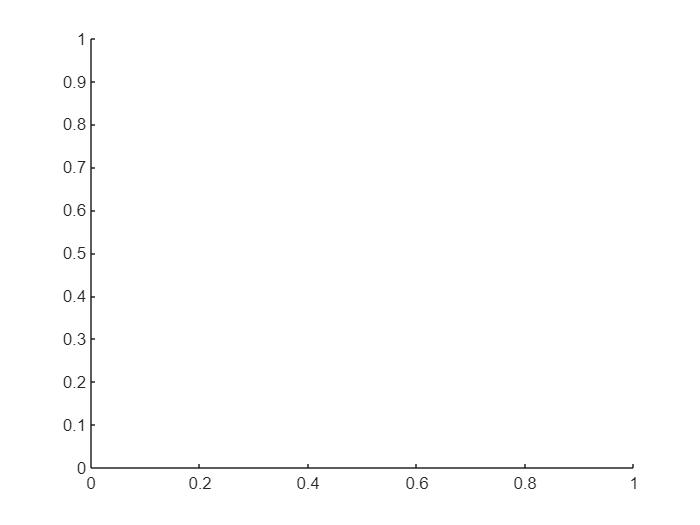

clf
hold on

plot3(prediction(1, :), prediction(2, :), prediction(3, :));

Reference to a cleared variable prediction.

plot3(X_ref(1, :), X_ref(2, :), X_ref(3, :));

clf
plot(prediction(1, 10:end)-X_ref(1, 10:end))
plot(prediction(2, 10:end)-X_ref(2, 10:end))
plot(prediction(3, 10:end)-X_ref(3, 10:end))


**2.4)**

Solve the data assimilation problem using a sequential importance sampling (SIS) approach, with two different proposal transition densities (your choice) selected out of the following list: 

- EnKF

w = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


X_prediction =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


n_eff = 3.1238

Reampling!


n_eff = 587.3602

n_eff = 577.2458

n_eff = 513.5365

n_eff = 176.0220

n_eff = 183.9930

n_eff = 331.2580

n_eff = 66.9497

Reampling!


n_eff = 995.2763

n_eff = 964.0829

n_eff = 905.3765

n_eff = 851.2632

n_eff = 711.1778

n_eff = 648.7624

n_eff = 642.0274

n_eff = 429.4259

n_eff = 365.5688

n_eff = 285.4553

n_eff = 149.5988

n_eff = 124.0463

n_eff = 66.7366

Reampling!


n_eff = 987.1026

n_eff = 989.0069

n_eff = 943.2792

n_eff = 633.9368

n_eff = 611.9189

n_eff = 574.9840

n_eff = 557.2883

n_eff = 590.6917

n_eff = 448.3823

n_eff = 431.8792

n_eff = 448.7273

n_eff = 409.3966

n_eff = 384.3063

n_eff = 356.8735

n_eff = 317.5605

n_eff = 304.7534

n_eff = 287.6015

n_eff = 281.7067

n_eff = 249.6298

n_eff = 237.7594

n_eff = 225.0181

n_eff = 208.3812

n_eff = 201.6429

n_eff = 196.4864

n_eff = 196.0570

n_eff = 196.6550

n_eff = 189.2151

n_eff = 181.4172

n_eff = 177.4915

n_eff = 177.7111

n_eff = 175.2611

n_eff = 172.3838

n_eff = 180.2793

n_eff = 176.8976

n_eff = 169.2437

n_eff = 160.8617

n_eff = 156.3889

n_eff = 156.0075

n_eff = 146.0369

n_eff = 146.9743

n_eff = 143.0376

n_eff = 142.8818

n_eff = 143.1396

n_eff = 139.8731

n_eff = 142.3418

n_eff = 137.0879

n_eff = 134.2798

n_eff = 136.6130

n_eff = 133.8624

n_eff = 128.3834

n_eff = 129.9036

n_eff = 131.8624

n_eff = 133.6555

n_eff = 124.5840

n_eff = 110.2438

n_eff = 108.6108

n_eff = 98.7070

Reampling!


n_eff = 996.6635

n_eff = 997.5129

n_eff = 990.5754

n_eff = 979.4809

n_eff = 974.1510

n_eff = 985.8976

n_eff = 975.6659

n_eff = 967.4091

n_eff = 959.5035

n_eff = 953.0316

n_eff = 913.4519

n_eff = 903.4103

n_eff = 893.1654

n_eff = 894.4020

n_eff = 885.8234

n_eff = 866.5732

n_eff = 850.4697

n_eff = 830.7657

n_eff = 764.4948

n_eff = 728.2056

n_eff = 733.7027

n_eff = 715.2588

n_eff = 732.4065

n_eff = 751.5388

n_eff = 725.8452

n_eff = 671.7099

n_eff = 657.1523

n_eff = 629.9243

n_eff = 601.0949

n_eff = 590.6964

n_eff = 599.1285

n_eff = 593.2480

n_eff = 599.3986

n_eff = 599.6099

n_eff = 601.7020

n_eff = 578.5654

n_eff = 556.5240

n_eff = 497.8525

n_eff = 485.8024

n_eff = 471.1768

n_eff = 441.0640

n_eff = 455.0626

n_eff = 440.7353

n_eff = 428.9186

n_eff = 447.4822

n_eff = 425.2810

n_eff = 413.8500

n_eff = 424.1801

n_eff = 409.6823

n_eff = 388.1973

n_eff = 400.7355

n_eff = 391.1984

n_eff = 375.5335

n_eff = 360.2812

n_eff = 341.5277

n_eff = 334.2932

n_eff = 321.2683

n_eff = 314.6422

n_eff = 313.8457

n_eff = 311.6456

n_eff = 305.3513

n_eff = 295.4991

n_eff = 297.2123

n_eff = 287.7838

n_eff = 285.8757

n_eff = 271.9129

n_eff = 263.7277

n_eff = 253.8141

n_eff = 249.9121

n_eff = 244.8198

n_eff = 236.4751

n_eff = 224.7216

n_eff = 217.2062

n_eff = 209.2622

n_eff = 198.5167

n_eff = 192.3352

n_eff = 186.4472

n_eff = 173.9944

n_eff = 169.5404

n_eff = 161.7183

n_eff = 150.9915

n_eff = 146.8055

n_eff = 143.5444

n_eff = 136.5376

n_eff = 127.4074

n_eff = 125.8025

n_eff = 112.1826

n_eff = 106.5979

n_eff = 105.6003

n_eff = 101.4513

n_eff = 93.6007

Reampling!


n_eff = 987.6012

n_eff = 974.9625

n_eff = 966.7022

n_eff = 978.6473

n_eff = 966.8077

n_eff = 975.0811

n_eff = 975.0995

n_eff = 966.5706

n_eff = 949.7134

n_eff = 942.1113

n_eff = 927.2168

n_eff = 893.9166

n_eff = 879.0082

n_eff = 872.6985

n_eff = 823.9585

n_eff = 804.7705

n_eff = 787.9433

n_eff = 781.8717

n_eff = 760.2526

n_eff = 741.8605

n_eff = 710.4891

n_eff = 645.0380

n_eff = 633.5542

n_eff = 611.1297

n_eff = 568.3697

n_eff = 474.5367

n_eff = 478.0836

n_eff = 341.4518

n_eff = 342.7193

n_eff = 335.4811

n_eff = 320.6906

n_eff = 281.1582

n_eff = 237.3761

n_eff = 173.1713

n_eff = 152.8963

n_eff = 147.9119

n_eff = 148.4690

n_eff = 142.3424

n_eff = 106.2398

n_eff = 100.0278

n_eff = 88.7436

Reampling!


n_eff = 995.7816

n_eff = 995.9744

n_eff = 982.6703

n_eff = 978.2457

n_eff = 965.4150

n_eff = 949.3149

n_eff = 927.5489

n_eff = 930.6740

n_eff = 906.2802

n_eff = 912.3453

n_eff = 886.8887

n_eff = 809.0621

n_eff = 666.3358

n_eff = 591.3211

n_eff = 579.2658

n_eff = 573.3878

n_eff = 543.5886

n_eff = 420.7342

n_eff = 271.2591

n_eff = 194.9491

n_eff = 163.7055

n_eff = 160.4669

n_eff = 156.3821

n_eff = 153.6296

n_eff = 107.0052

n_eff = 73.9013

Reampling!


n_eff = 995.0686

n_eff = 967.3262

n_eff = 943.6259

n_eff = 943.8124

n_eff = 941.6818

n_eff = 932.7274

n_eff = 868.3327

n_eff = 542.2599

n_eff = 175.6520

n_eff = 86.8551

Reampling!


n_eff = 818.2611

n_eff = 749.0885

n_eff = 768.7758

n_eff = 767.3383

n_eff = 766.4840

n_eff = 739.1138

n_eff = 724.2750

n_eff = 710.7532

n_eff = 697.4315

n_eff = 707.8051

n_eff = 707.5310

n_eff = 705.1087

n_eff = 681.4687

n_eff = 662.4459

n_eff = 587.7264

n_eff = 579.2614

n_eff = 579.9134

n_eff = 565.6530

n_eff = 454.3742

n_eff = 149.7646

n_eff = 107.3038

n_eff = 45.5677

Reampling!


n_eff = 996.0601

n_eff = 996.7151

n_eff = 996.6660

n_eff = 988.1303

n_eff = 974.3057

n_eff = 874.8398

n_eff = 459.8523

n_eff = 128.4919

n_eff = 87.9511

Reampling!


n_eff = 999.4535

n_eff = 999.3000

n_eff = 999.1365

n_eff = 996.7796

n_eff = 995.8245

n_eff = 994.9770

n_eff = 991.7991

n_eff = 986.0575

n_eff = 986.9938

n_eff = 982.2748

n_eff = 978.6704

n_eff = 912.5504

n_eff = 788.7794

n_eff = 482.0769

n_eff = 466.6736

n_eff = 461.2927

n_eff = 462.0185

n_eff = 459.0974

n_eff = 414.3948

n_eff = 195.1879

n_eff = 69.1669

Reampling!


n_eff = 311.5462

n_eff = 11.3606

Reampling!


n_eff = 219.9017

n_eff = 143.8123

n_eff = 108.3094

n_eff = 110.8997

n_eff = 110.3134

n_eff = 110.5239

n_eff = 110.6211

n_eff = 110.3256

n_eff = 109.4413

n_eff = 108.2568

n_eff = 106.2407

n_eff = 106.0101

n_eff = 105.5109

n_eff = 104.9806

n_eff = 104.3907

n_eff = 102.8802

n_eff = 106.3440

n_eff = 106.3772

n_eff = 106.4655

n_eff = 105.3977

n_eff = 106.5883

n_eff = 102.2167

n_eff = 100.9259

n_eff = 101.6195

n_eff = 97.9318

Reampling!


n_eff = 994.8913

n_eff = 993.5378

n_eff = 991.9655

n_eff = 989.2108

n_eff = 988.8977

n_eff = 984.3973

n_eff = 977.8307

n_eff = 966.1677

n_eff = 958.2888

n_eff = 934.9432

n_eff = 925.2522

n_eff = 910.6240

n_eff = 907.3708

n_eff = 877.9029

n_eff = 822.8663

n_eff = 812.1883

n_eff = 765.8610

n_eff = 756.7673

n_eff = 749.9574

n_eff = 734.7697

n_eff = 662.4137

n_eff = 639.1071

n_eff = 498.4972

n_eff = 471.6743

n_eff = 458.0479

n_eff = 462.2545

n_eff = 429.1013

n_eff = 337.0610

n_eff = 308.9015

n_eff = 232.4768

n_eff = 218.9730

n_eff = 217.6351

n_eff = 212.6414

n_eff = 190.0135

n_eff = 134.7252

n_eff = 104.1036

n_eff = 71.9313

Reampling!


n_eff = 997.0948

n_eff = 997.8069

n_eff = 996.9328

n_eff = 990.5031

n_eff = 969.0904

n_eff = 843.9796

n_eff = 683.7160

n_eff = 579.5632

n_eff = 573.6491

n_eff = 572.7861

n_eff = 567.2449

n_eff = 538.8936

n_eff = 312.6817

n_eff = 103.4202

n_eff = 46.5382

Reampling!


n_eff = 999.3328

n_eff = 995.7316

n_eff = 992.6662

n_eff = 992.9257

n_eff = 985.8142

n_eff = 981.6908

n_eff = 978.4467

n_eff = 988.9838

n_eff = 986.7548

n_eff = 985.3114

n_eff = 980.2108

n_eff = 982.4148

n_eff = 967.3447

n_eff = 945.6337

n_eff = 869.5381

n_eff = 857.2993

n_eff = 852.2900

n_eff = 849.7055

n_eff = 830.3314

n_eff = 710.9483

n_eff = 350.9849

n_eff = 231.3742

n_eff = 155.3322

n_eff = 148.4153

n_eff = 148.8005

n_eff = 147.8663

n_eff = 146.2676

n_eff = 121.6330

n_eff = 53.1271

Reampling!


n_eff = 972.1778

n_eff = 891.5170

n_eff = 859.1825

n_eff = 859.3666

n_eff = 859.8134

n_eff = 856.4648

n_eff = 855.8932

n_eff = 851.0619

n_eff = 823.1200

n_eff = 834.1549

n_eff = 822.9202

n_eff = 786.2277

n_eff = 807.8036

n_eff = 647.5537

n_eff = 381.2637

n_eff = 272.4919

n_eff = 202.3172

n_eff = 192.8802

n_eff = 192.8344

n_eff = 191.8786

n_eff = 182.2695

n_eff = 114.4239

n_eff = 66.5541

Reampling!


n_eff = 986.2778

n_eff = 865.1753

n_eff = 856.6419

n_eff = 860.8599

n_eff = 857.3641

n_eff = 860.0055

n_eff = 847.6750

n_eff = 849.5941

n_eff = 842.6292

n_eff = 834.4974

n_eff = 835.6146

n_eff = 839.3779

n_eff = 820.8235

n_eff = 749.6190

n_eff = 249.0902

n_eff = 131.4954

n_eff = 79.1048

Reampling!


n_eff = 999.2683

n_eff = 995.8156

n_eff = 995.0720

n_eff = 995.6863

n_eff = 988.7572

n_eff = 985.0229

n_eff = 974.1438

n_eff = 923.9826

n_eff = 924.3393

n_eff = 921.0009

n_eff = 914.1684

n_eff = 889.3172

n_eff = 641.7563

n_eff = 233.1154

n_eff = 71.1349

Reampling!


n_eff = 784.4219

n_eff = 148.1001

n_eff = 80.6946

Reampling!


n_eff = 997.2273

n_eff = 996.2908

n_eff = 994.7239

n_eff = 993.9735

n_eff = 995.6250

n_eff = 995.0366

n_eff = 992.7443

n_eff = 993.7926

n_eff = 992.4955

n_eff = 992.4560

n_eff = 991.3085

n_eff = 990.8246

n_eff = 984.6037

n_eff = 981.7406

n_eff = 979.5821

n_eff = 982.3855

n_eff = 974.5294

n_eff = 978.7754

n_eff = 975.3479

n_eff = 964.6147

n_eff = 962.1602

n_eff = 958.8466

n_eff = 949.2030

n_eff = 920.9496

n_eff = 918.7166

n_eff = 863.0638

n_eff = 834.4499

n_eff = 827.6236

n_eff = 823.7016

n_eff = 799.5710

n_eff = 708.1512

n_eff = 631.9549

n_eff = 447.9393

n_eff = 426.2628

n_eff = 427.3693

n_eff = 425.1122

n_eff = 406.6243

EnKF run complete


rmse_particle =     0.0049    0.0102    0.0124    0.0143    0.0120    0.0113    0.0132    0.0132    0.0138    0.0160    0.0157    0.0132    0.0156    0.0154    0.0128    0.0149    0.0140    0.0119    0.0135    0.0118    0.0097    0.0105    0.0097    0.0088    0.0095    0.0057    0.0053    0.0063    0.0056    0.0056    0.0053    0.0044    0.0045    0.0053    0.0047    0.0044    0.0045    0.0037    0.0039    0.0046    0.0038    0.0039    0.0040    0.0032    0.0037    0.0043    0.0037    0.0039    0.0041    0.0033


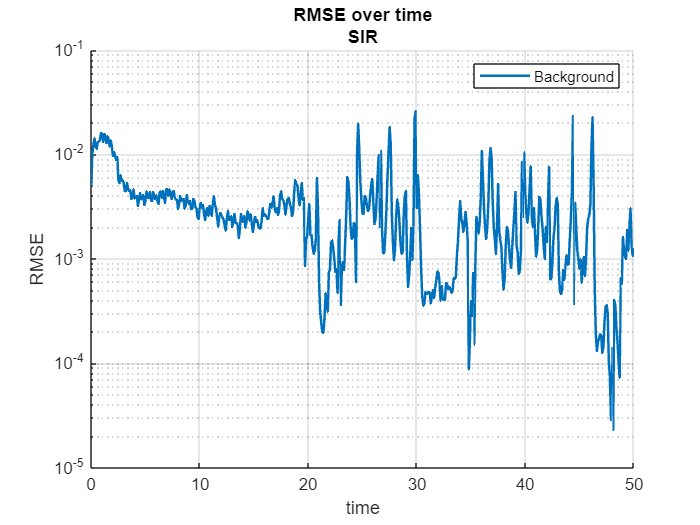

prediction = donald_ENKF_63b(m, X_ens_b, X_obvs_ens, X_ref, H, time_steps, n_states, n_particles, 1);

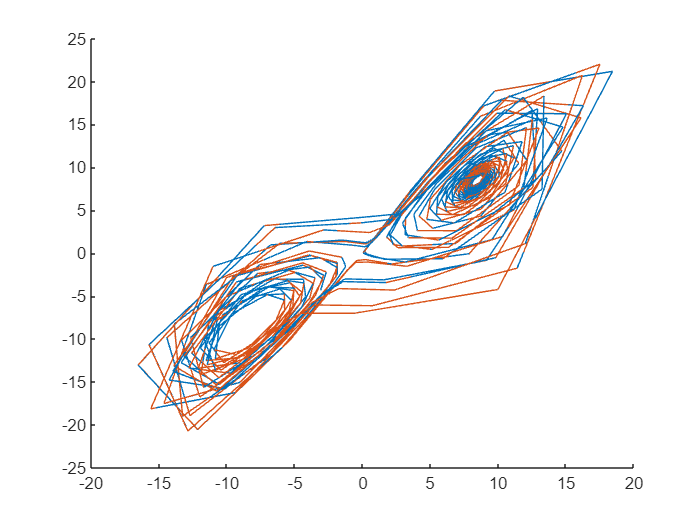

clf
hold on
plot3(prediction(1, :), prediction(2, :), prediction(3, :));
plot3(X_ref(1, :), X_ref(2, :), X_ref(3, :));

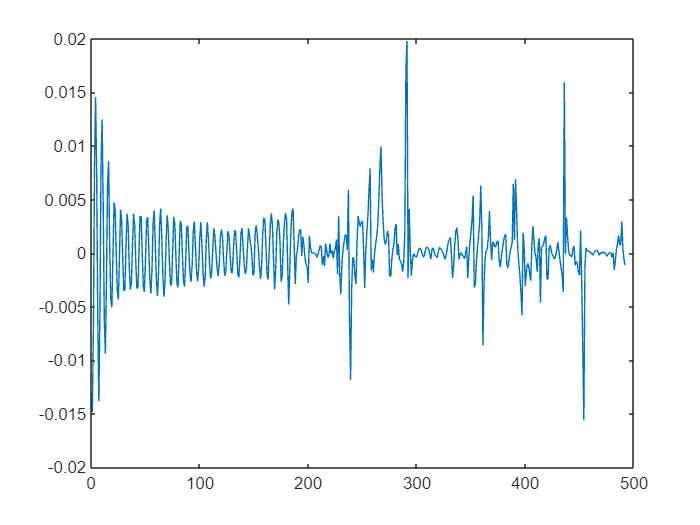


clf
plot(prediction(1, 10:end)-X_ref(1, 10:end))

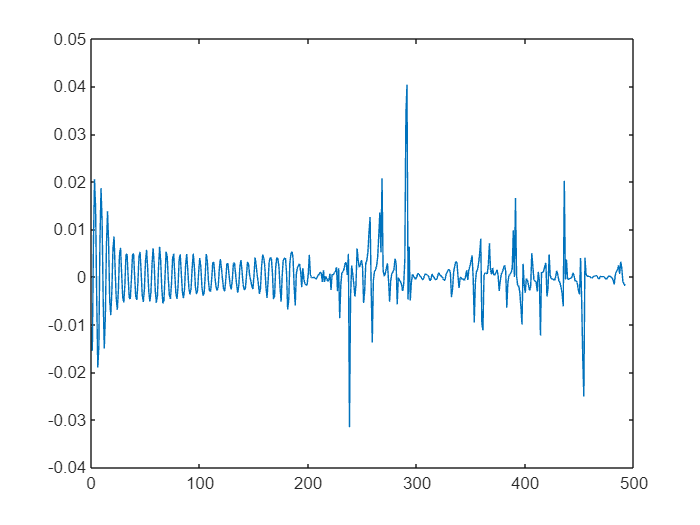

plot(prediction(2, 10:end)-X_ref(2, 10:end))

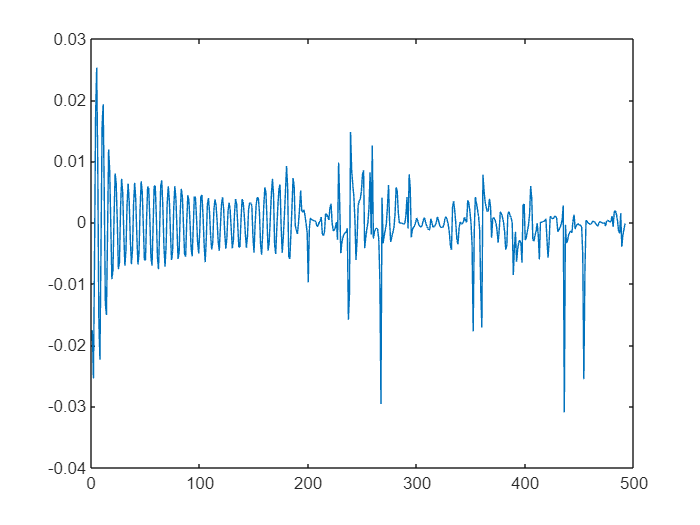

plot(prediction(3, 10:end)-X_ref(3, 10:end))

**2.5)**

- Apply cov

- ariance localization. Use a Gaspari-Cohn function with a decorrelation parameter L = 5.

- Repeat the EnKF and ETKF numerical experiments and compare the results against the analysis obtained without localization.

% Updated filter configurations (covar localization)
covar_localization = 1; % True
covar_inflation = 0; % False

[X_ens_array] = donald_EnKF(m, X_ens_b, X_obvs_ens,X_ref, H, time_steps, R, n_states, n_ens, covar_localization, covar_inflation, L, alpha, plot);

Unrecognized function or variable 'L'.

[X_ens_array] = donald_LETKF(m, X_ens_b,X_obvs, X_obvs_ens, X_ref, H, time_steps, n_states, n_ens, covar_inflation, L, alpha, plot);

**2.6)**

- In addition to localization, apply multiplicative covariance inflation with a parameter α = 1.02.

-  Again, repeat the EnKF and ETKF numerical experiments, and compare the results against the analysis obtained before. 

% Filter configurations (localization and covar inflation)
covar_localization = 1; % True
covar_inflation = 1; % False


[X_ens_array] = donald_EnKF(m, X_ens_b, X_obvs_ens,X_ref, H, time_steps, R, n_states, n_ens, covar_localization, covar_inflation, L, alpha, plot);
covar_localization = 0; % Should be True - but localization for ETKF not implemented yet!

[X_ens_array] = donald_LETKF(m, X_ens_b, X_obvs, X_obvs_ens, X_ref, H, time_steps, n_states, n_ens, covar_inflation, L, alpha, plot);